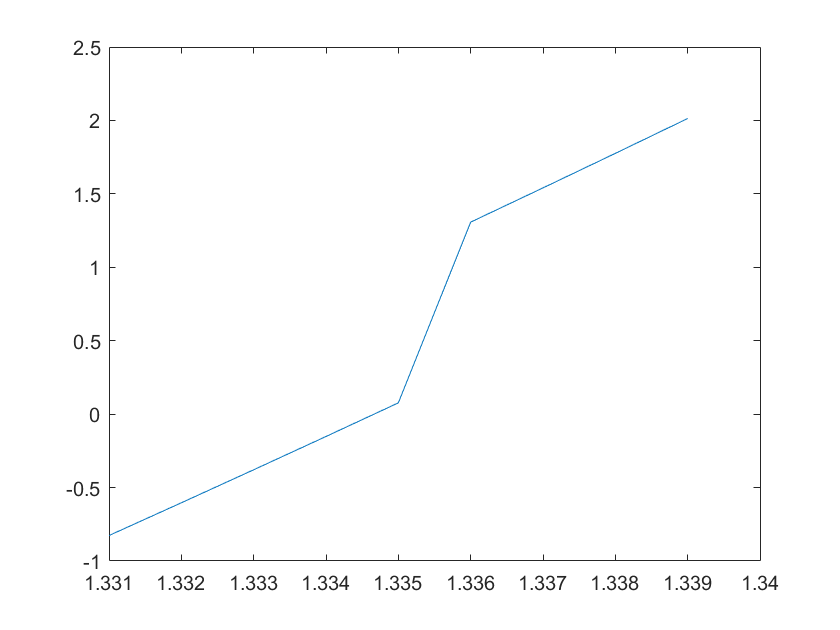

m = input("Enter value for mode (m): ");
phi_inc = input("Azimuthal angle: ");
theta_inc = input("Incident angle: ");
grating_thickness = input("Grating thickness in nm: ");
grating_length = input("Grating length in um: ");
fill_factor = input("Fill factor: ");
material_RI = input("RI of grating material: ");
cover_RI = input("Initial RI of cover: ");
wavelength = input("Wavelength in nm: ");
substrate_RI = input("RI of substrate: ");
step_change_in_RI = input("Step change in cover RI: ");
Number_of_steps = input("Number of steps: ");

max_nv = max_n(grating_thickness, waveguide_eff_RI(cover_RI, material_RI, fill_factor), substrate_RI, grating_length);
N = input("Enter value of Number of round trips which is < " + int2str(max_nv) + ": ");
%disp(waveguide_eff_RI(cover_RI, material_RI, fill_factor));

delta_phase = [];
delta_n = [];
r=[];
p=[];
slp=[];
for i = cover_RI:step_change_in_RI:(cover_RI + step_change_in_RI*Number_of_steps)
     z= effective_RI(theta_inc, phi_inc, m, wavelength, i);
     n_w = waveguide_eff_RI(i, material_RI, fill_factor);
    if z<n_w && z>substrate_RI
        p = [p total_phase(N,(total_phase_TM(theta_inc, phi_inc, m, wavelength, i, n_w)))/pi];
        %disp(total_phase(N,(total_phase_TM(theta_inc, phi_inc, m, wavelength, i, n_w))));
        r = [r i];
    end
end

for j = 1:(length(r))
    delta_phase = [delta_phase (p(j)-p(1))];
    delta_n = [delta_n (r(j)-r(1))];
end

ph=[];
d=0;
for j = 1:(length(r))
    if j == 1
        ph = [ph p(1)];
    else
        if p(j) < p(j-1)
            d=d+1;
        end
        ph = [ph p(j)+2*d];
    end
end
%plot(delta_n,delta_phase)
%plot(r,p)
%the resason for plot periodicity is that angle() function gives the result
%periodic order
plot(r,ph)

function [n_eff] = effective_RI(theta_inc,phi_inc,m,wavelength,cover_RI)
% theta_inc= incidence angle
% phi_inc = azimuthal incidence angle
% m = mode
% wavelength= incidence wavelength
a= sind(theta_inc);
b= cosd(phi_inc);
c = (m*wavelength)/572;
n_1 = cover_RI;%incidence coating index
t_1 = (n_1*a);
t_2 = 2*t_1*b*c;
t_3 = c^2;
n_eff = sqrt((t_1^2)-t_2+t_3);
end

function [Total_phase] = total_phase_TM(theta_inc,phi_inc,m,wavelength,cover_RI, n_w)
a = optical_distance_phase(theta_inc,phi_inc,m,wavelength,cover_RI, n_w);% optical distance phase difference
b = TM_phi_ws(theta_inc,phi_inc,m,wavelength,cover_RI, n_w);% phase due to TIR at waveguide- substrate interface 
c = TM_phi_wf(theta_inc,phi_inc,m,wavelength,cover_RI, n_w);% phase due to TIR at waveguide- grating interface
Total_phase= a+b+c;
end

function [x_1]= optical_distance_phase(theta_inc,phi_inc,m,wavelength,cover_RI, n_w)
a = effective_RI(theta_inc,phi_inc,m,wavelength,cover_RI);
K = ((2*pi)/wavelength)*((((n_w)^2)-(a^2))^(1/2));
x_1 =(2*K*150);
end

function [x_3] = TM_phi_ws(theta_inc,phi_inc,m,wavelength,cover_RI, n_w)
n_1 = n_w;    %waveguide RI
n_2 = 1.45; %substrate RI
a = effective_RI(theta_inc,phi_inc,m,wavelength,cover_RI);
b = (n_1/n_2)^2;
c = abs(((a^2)-((n_2)^2))/(-(a^2)+((n_1)^2)));
x_3 = -2*atan(b*(sqrt(c)));
end

function [x_2] = TM_phi_wf(theta_inc,phi_inc,m,wavelength,cover_RI, n_w)
n_1 = n_w;    %waveguide RI
n_2 = cover_RI; %effecctive subwavelength grating RI
a = effective_RI(theta_inc,phi_inc,m,wavelength,cover_RI);    
b = (n_1/n_2)^2;
c = abs(((a^2)-((n_2)^2))/(-(a^2)+((n_1)^2)));
x_2 = -2*atan(b*(sqrt(c)));
end

function [nw] = waveguide_eff_RI(nl, nh, fill)
nw = 1/(sqrt((fill/(nh^2)) + ((1-fill)/(nl^2))));
end

function [N] = max_n(thicc, nw, ns, g_length)
N = g_length*1000/(2*thicc*tan(asin(ns/nw)));
end

function [T_phase] = total_phase(N,p)
sum= 0;
for m = 0:(N-1)
    e = 1i*(m*p);
    sum = sum + (exp(-e));
end
x = -(angle(sum));
%if x<0
%T_phase = 2*pi + x;
%else
T_phase = (x);
%end
end 


